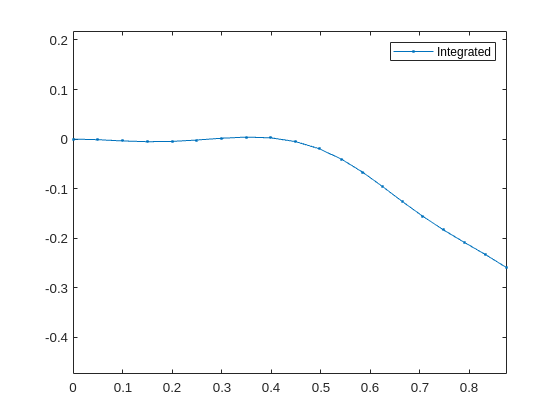

omega_1 = 10;
phase_1 = 0;
omega_2 = 3;
phase_2 = 1;

l = 1;
f_sin_curvature = @(s) [
    l;
    0;
    2*sin(s*omega_1) + 0*sin(s*omega_2 + phase_2) - 1;
];

g_0 = eye(3);
mat_poses = calc_poses(g_0, f_sin_curvature);

figure()
plot(mat_poses(1, :), mat_poses(2, :), ".-");
axis equal
legend("Integrated")

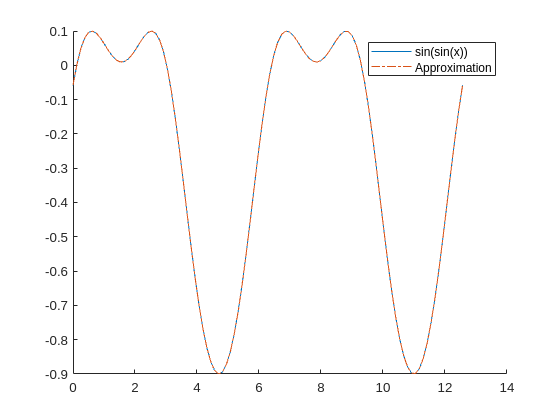

% Plot sin(sin(x)) and its Fourier seris approximation in terms of J
x = linspace(0, 4*pi, 100);

C_i = 1;
I_i = 1;

y = sin(C_i + I_i .* sin(x)) - 0.9;

freq_bound = 20;
ks = -freq_bound:freq_bound;
y_approx = zeros(size(y));

for i = 1 : length(ks)
    k_i = ks(i);
    % Fourier approximation source: https://www.jstor.org/stable/40731301?seq=2
    y_approx = y_approx + besselj(k_i, I_i) .* sin(C_i + k_i*x); 
end

y_approx = y_approx - 0.9;

figure()
hold on
plot(x, y);
plot(x, y_approx, "-.");
legend("sin(sin(x))", "Approximation")

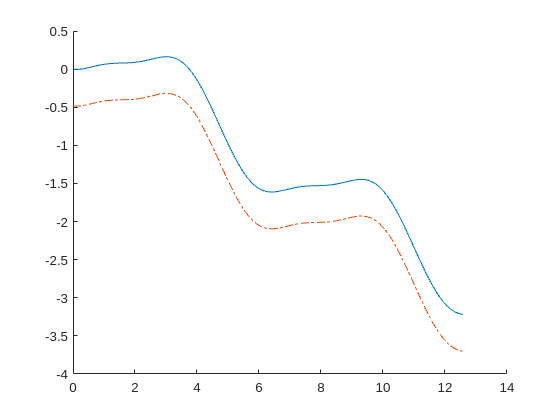

% Then plot its numerical integral, and the analytic fourier series
% approximaion for the integral
y_int = cumtrapz(x, y);

y_int_approx = zeros(size(y));
for i = 1 : length(ks)
    k_i = ks(i);
    if k_i ~= 0
        y_int_approx = y_int_approx + (-(1/k_i) .* besselj(k_i, I_i) .* cos(C_i + k_i*x));
    else
        y_int_approx = y_int_approx + besselj(k_i, I_i) .* sin(C_i) .* x;
    end
end
y_int_approx = y_int_approx - 0.9*x;

figure()
hold on
plot(x, y_int)
plot(x, y_int_approx, "-.")

function mat_poses = calc_poses(g_0, f_g_circ)
    N_pts = 20;
    s = linspace(0, 1, N_pts);
    ds = 1/N_pts;

    cell_poses = cell(1, N_pts);
    cell_poses{1} = g_0;
    for i = 1 : N_pts-1

        s_i = s(i);

        % Get the current twist
        g_circ_s = f_g_circ(s_i);

        % Compute the next displacement
        delta_g = Twist2.expm(g_circ_s*ds);

        % Apply the next displacement
        cell_poses{i+1} = cell_poses{i} * delta_g;
    end
    
    mat_poses = zeros(3, N_pts);
    for i = 1 : N_pts
        mat_poses(:, i) = Pose2.vee(cell_poses{i});
    end
end